# **Implementación EC en matlab de modulación digital y analógica**

Andrés Fernando Jerez Medina - 2190416

Jorge Eduardo Angarita Perez - 2190427

Sergio Sebastián Oliveros Sepulveda - 2190396

## **Punto 1**

Se implementan las señales x(t) y y(t) de la envolvente compleja para una modulación 8PSK con un tiempo de 0.05 segundos, para transmitir la secuencia de bits 101100111001 (asumiendo que se transmiten de derecha a izquierda).

Parámetros

Tb = 0.05;      %Tiempo de Bit
sps = 16;        %Muestras por símbolo (Personalizado by us)
L = 3;          %# de Bits que conforman un Símbolo

Ts = Tb/sps;    %Tiempo de Muestreo
fs = 1/Ts;      %Frecuencia de Muestreo

Ac = 1;         %Amplitud Portadora
fc = 1/(Ts*8);  %Frecuencia de portadora 

En este caso, se usa un valor de amplitud de 1 dado que se va a realizar la modulación en fase, un valor de sps de 8 muestras por simbolo y la cantidad de bits que se agrupan será de 3, porque $M=2^L \;$ y $M=8$.

El tiempo de muestreo usado es el tiempo de bit dividido en la cantidad de muestras por simbolo, de esa manera se podrá observar las señales perfectamente. Y finalmente, la frecuencia de portadora se escogió como 8 veces la frecuencia de muestreo.

Bits

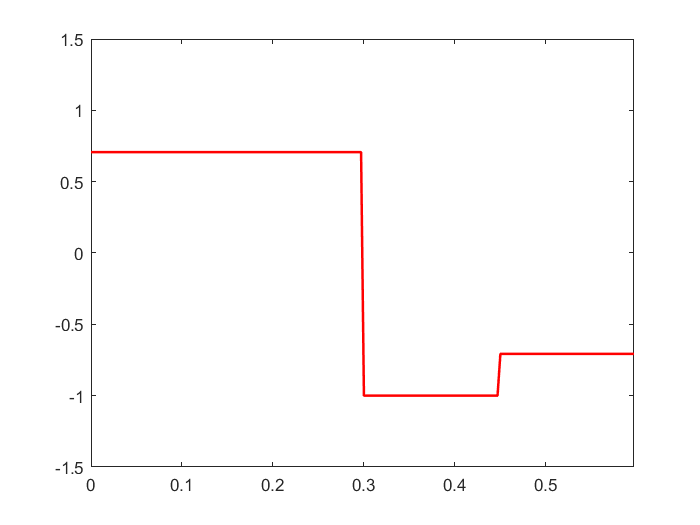

bits = [1 0 1 1 0 0 1 1 1 0 0 1];                %Bits de llegada
NBit = length(bits);                             %Número de Bits 
t = 0:Ts:Tb*NBit-Ts;                             %Tiempo
Nsamples = NBit*sps;                             %Número de Muestras
sym = bit2sym(bits,L);
m_t = vect2samp(bits,sps);
sym_t = vect2samp(sym, sps*L);       
g_t = Ac*exp(1j*sym_t*pi/4);                     %Envolvente compleja
x_t = real(g_t);                                 %Componente en Fase
y_t = imag(g_t);                                 %Componente en cuadratura
s_t = x_t.*cos(2*pi*fc*t)-y_t.*sin(2*pi*fc*t);     %Señal Modulada
plot(t,x_t,'color','r','linewidth',1.5)
xlim([0 Tb*NBit-Ts])
ylim([-1.5 1.5])

Se puede observar que la señal x(t) puede tomar 4 valores diferentes, asociados a cada posición del diagrama de constelaciones mostrado en el documento guía.


$$x\left(t\right)=\left\lbrack \begin{array}{cc}
1 & ,\;\mathrm{para}\;\mathrm{la}\;\mathrm{posición}\;1\;\mathrm{del}\;\mathrm{diagrama}\\
\sqrt{2} & ,\;\mathrm{para}\;\mathrm{las}\;\mathrm{posiciones}\;2\;y\;8\;\mathrm{del}\;\mathrm{diagrama}\\
0 & ,\;\mathrm{para}\;\mathrm{las}\;\mathrm{posiciones}\;\;3\;y\;7\;\mathrm{del}\;\mathrm{diagrama}\\
-\sqrt{2} & ,\;\mathrm{para}\;\mathrm{las}\;\mathrm{posiciones}\;4\;y\;6\;\;\mathrm{del}\;\mathrm{diagrama}\\
-1 & ,\;\mathrm{para}\;\mathrm{la}\;\mathrm{posición}\;5\;\;\mathrm{del}\;\mathrm{diagrama}
\end{array}\right\rbrack$$


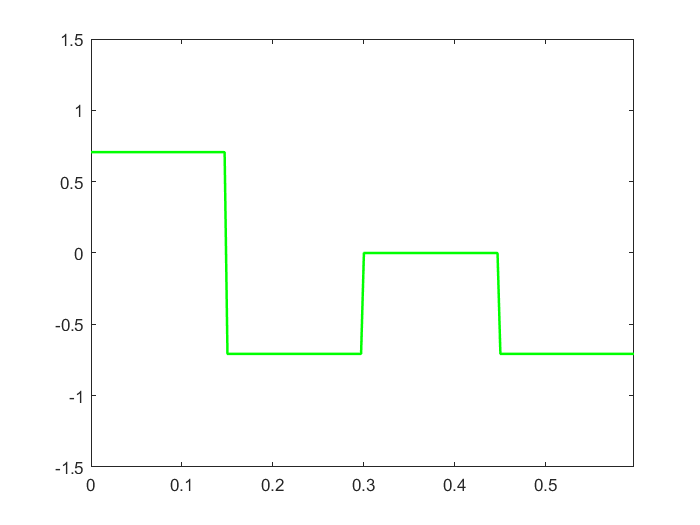

plot(t,y_t,'color','g','linewidth',1.5)
xlim([0 Tb*NBit-Ts])
ylim([-1.5 1.5])

De la misma forma la gráfica de la señal y(t) también se aprecia tomando diferentes valores dependiendo de la posición en el diagrama de constelaciones.

Se puede observar que la señal x(t) puede tomar 4 valores diferentes, asociados a cada posición del diagrama de constelaciones mostrado en el documento guía.


$$y\left(t\right)=\left\lbrack \begin{array}{cc}
1 & ,\;\mathrm{para}\;\mathrm{la}\;\mathrm{posición}\;3\;\mathrm{del}\;\mathrm{diagrama}\\
\sqrt{2} & ,\;\mathrm{para}\;\mathrm{las}\;\mathrm{posiciones}\;2\;y\;4\;\mathrm{del}\;\mathrm{diagrama}\\
0 & ,\;\mathrm{para}\;\mathrm{las}\;\mathrm{posiciones}\;\;1\;y\;5\;\mathrm{del}\;\mathrm{diagrama}\\
-\sqrt{2} & ,\;\mathrm{para}\;\mathrm{las}\;\mathrm{posiciones}\;6\;y\;8\;\;\mathrm{del}\;\mathrm{diagrama}\\
-1 & ,\;\mathrm{para}\;\mathrm{la}\;\mathrm{posición}\;7\;\;\mathrm{del}\;\mathrm{diagrama}
\end{array}\right\rbrack$$


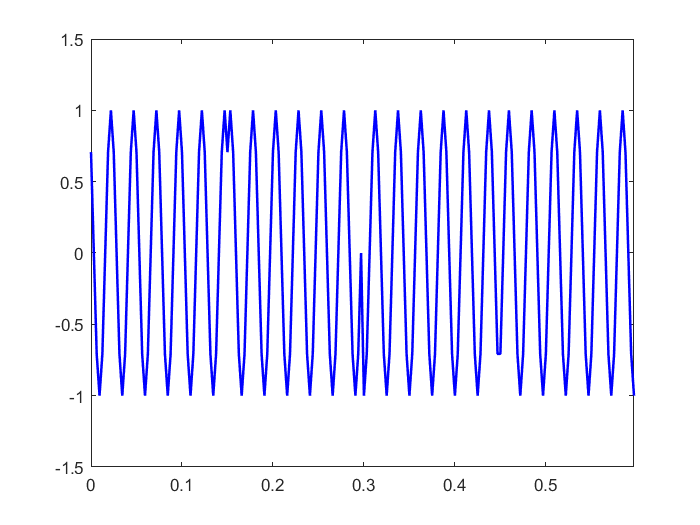

plot(t,s_t,'color','b','linewidth',1.5)

xlim([0 Tb*NBit-Ts])
ylim([-1.5 1.5])

Finalmente se muestra la gráfica de la señal modulada s(t), donde es posible apreciar que en los momentos de tiempo que coinciden con los cambios en los valores de x(t) y y(t), la señal modulada s(t) presenta un desfase. Esto es como tal, la modulación 8PSK.

Frecuencia:

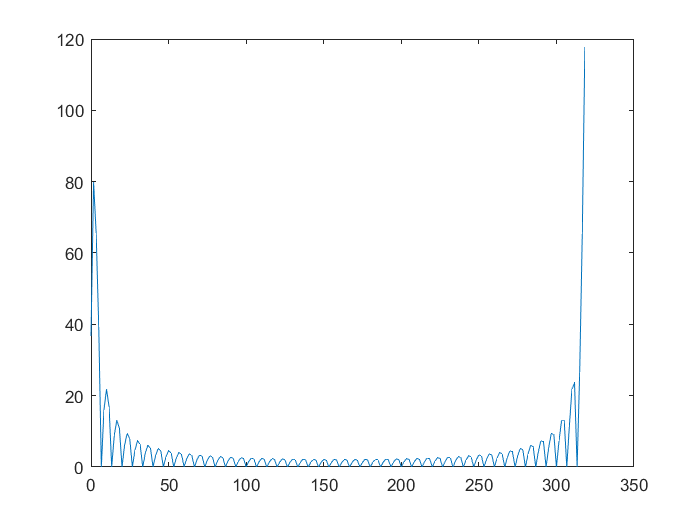

n = length(t);
f = (0:n-1)*(fs/n);
m_f = fft(m_t);
g_f = fft(g_t);
s_f = fft(s_t);
plot(f,abs(g_f))

Funciones:

function [sym, bitOrder] = bit2sym(bits, L) %Para generar los símbolos
    NBit = length(bits);
    Power2 = 2.^(L-1:-1:0);
    Nsteps = NBit/L;
    sym = zeros(1,Nsteps);
    for i = 1:Nsteps
        BitAct = bits(end-i*L+1:end-(i-1)*L);
        sym(i) = dot(Power2,BitAct);
    end
end

function m = vect2samp(vect, sps) %Para pasar de los bits al tiempo muestreado
    Nvect = length(vect);
    m = zeros(1, sps*Nvect);
    for i = 1:Nvect
        m((i-1)*sps+1:i*sps) = vect(i);
    end
end